true_x = out.truePose.Estimatex.data;
true_y = out.truePose.Estimatey.data;
true_z = out.truePose.Estimatez.data;
true_roll = out.truePose.EstimateRoll.data;
true_pitch = out.truePose.EstimatePitch.data;
true_yaw = out.truePose.EstimateYaw.data;
sim_x = out.simPose.x.data;
sim_y = out.simPose.y.data;
sim_z = out.simPose.z.data;
sim_roll = out.simPose.signal___1.data;
sim_pitch = out.simPose.signal___2.data;
sim_yaw = out.simPose.signal___3.data;
input_x_data = input_x(1:length(sim_x),2);
input_y_data = input_y(1:length(sim_x),2);
input_z_data = input_z(1:length(sim_x),2);
input_yaw_data = input_yaw(1:length(sim_x),2);

RMSE_x = rmse(sim_x, true_x)*1000

RMSE_x = 26.0671

RMSE_y = rmse(sim_y, true_y)*1000

RMSE_y = 24.8472

RMSE_z = rmse(sim_z, true_z)*1000

RMSE_z = 20.8013

RMSE_roll = rad2deg(rmse(sim_roll, true_roll))

RMSE_roll = 1.7081

RMSE_pitch = rad2deg(rmse(sim_pitch, true_pitch))

RMSE_pitch = 1.6883

RMSE_yaw = rad2deg(rmse(sim_yaw, true_yaw))

RMSE_yaw = 5.6482

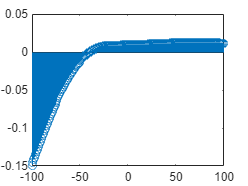


error_x = sim_x - true_x;
% error_x = timeseries(error_x,time,"Name",error_x)
[c, lags] = xcorr(input_x_data, error_x,100,'normalized');
% [c, lags] = xcorr(error_y, input_y_data,100,'normalized');
% [c, lags] = xcorr(error_z, input_z_data,100,'normalized');
stem(lags, c)

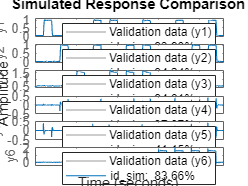

id_sim = iddata([sim_x, sim_y, sim_z, sim_roll, sim_pitch, sim_yaw],[input_x_data, input_y_data, input_z_data, input_yaw_data],0.01);
id_true = iddata([true_x, true_y, true_z, true_roll, true_pitch, true_yaw], [input_x_data, input_y_data, input_z_data, input_yaw_data], 0.01);
compare(id_true, id_sim)